Задание 4.

i = 5;
P = -2:(.4/i):2;
T = 1 + sin(i * pi * P / 4);
P1 = -2:(.4/i):2;

S1 = 5;
net = fitnet(S1)

net =

    Neural Network
 
              name: 'Function Fitting Neural Network'
          userdata: (your custom info)
 
    dimensions:
 
         numInputs: 1
         numLayers: 2
        numOutputs: 1
    numInputDelays: 0
    numLayerDelays: 0
 numFeedbackDelays: 0
 numWeightElements: 5
        sampleTime: 1
 
    connections:
 
       biasConnect: [1; 1]
      inputC

net.trainParam.goal = 0.001;
net.trainParam.show = NaN;
net.trainParam.epochs = 1;
net.trainParam.showWindow = false

net =

    Neural Network
 
              name: 'Function Fitting Neural Network'
          userdata: (your custom info)
 
    dimensions:
 
         numInputs: 1
         numLayers: 2
        numOutputs: 1
    numInputDelays: 0
    numLayerDelays: 0
 numFeedbackDelays: 0
 numWeightElements: 5
        sampleTime: 1
 
    connections:
 
       biasConnect: [1; 1]
      inputC

[net, tr] = train(net, P, T);
Y1 = net(P1);

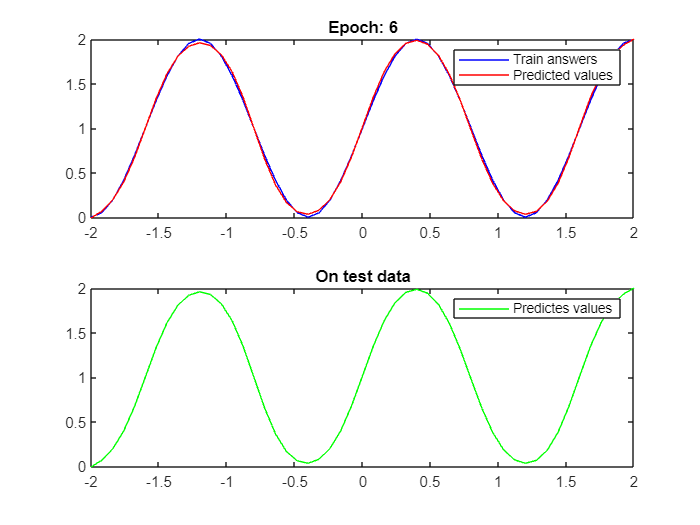

Training ends here: 6


epochs = 100;
figure;

for epoch = 1:epochs
    [net, tr] = train(net, P, T);
    
    Y1 = net(P1);
    
    subplot(2, 1, 1);
    plot(P, T, 'b', P, net(P), 'r');
    title(['Epoch: ' num2str(epoch)]);
    legend('Train answers', 'Predicted values');
    
    subplot(2, 1, 2);
    plot(P1, Y1, 'g');
    title('On test data');
    legend('Predictes values');
    
    drawnow;
    
    if tr.best_perf <= net.trainParam.goal
        disp(['Training ends here: ' num2str(epoch)]);
        break;
    end
end

disp(tr)

        trainFcn: 'trainlm'
      trainParam: [1×1 struct]
      performFcn: 'mse'
    performParam: [1×1 struct]
        derivFcn: 'defaultderiv'
       divideFcn: 'dividerand'
      divideMode: 'sample'
     divideParam: [1×1 struct]
        trainInd: [3 4 5 6 7 8 10 12 13 14 15 18 19 23 24 25 30 31 32 33 35 36 38 39 40 42 43 44 45 46 47 48 49 50 51]
          valInd: [2 9 11 20 26 27 28 29]
         testInd: [1 16 17 21 22 34 37 41]
            stop: 'Training finished: Reached maximum number of epochs'
      num_epochs: 1
       trainMask: {[NaN NaN 1 1 1 1 1 1 NaN 1 NaN 1 1 1 1 NaN NaN 1 1 NaN NaN NaN 1 1 1 NaN NaN NaN NaN 1 1 1 1 NaN 1 1 NaN 1 1 1 NaN 1 1 1 1 1 1 1 1 1 1]}
         valMask: {[NaN 1 NaN NaN NaN NaN NaN NaN 1 NaN 1 NaN NaN NaN NaN NaN NaN NaN NaN 1 NaN NaN NaN NaN NaN 1 1 1 1 NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN]}
        testMask: {[1 NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN 1 1 NaN NaN NaN 1 1 NaN 

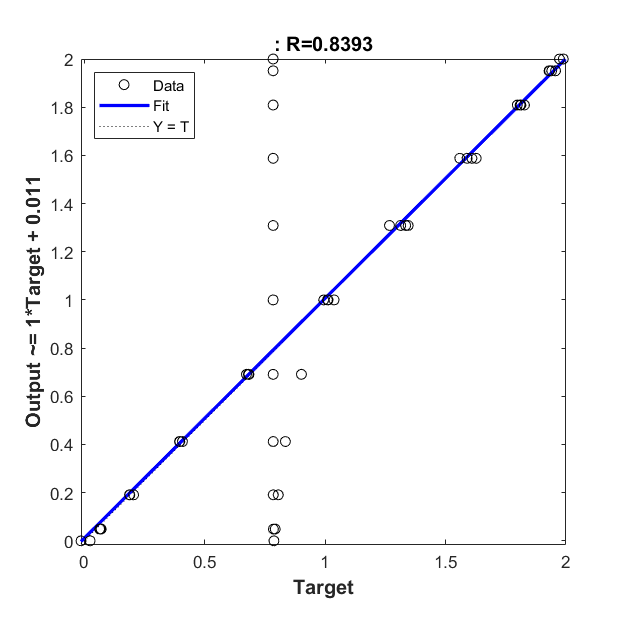

plotregression(Y1, T)

Задание 5.

appdesigner

L = 101;
noise = rand(L, L) * 1.5 - 0.75;

[X, Y] = meshgrid(-5:0.1:5, -5:0.1:5);
Z = 5 * X .* X - 3 * Y;
P = [X; Y];
T = Z + noise;

[X_test, Y_test] = meshgrid(-5:0.1:5, -5:0.1:5);
Z = 5 * X .* X - 3 * Y;
P_test = [X_test; Y_test];

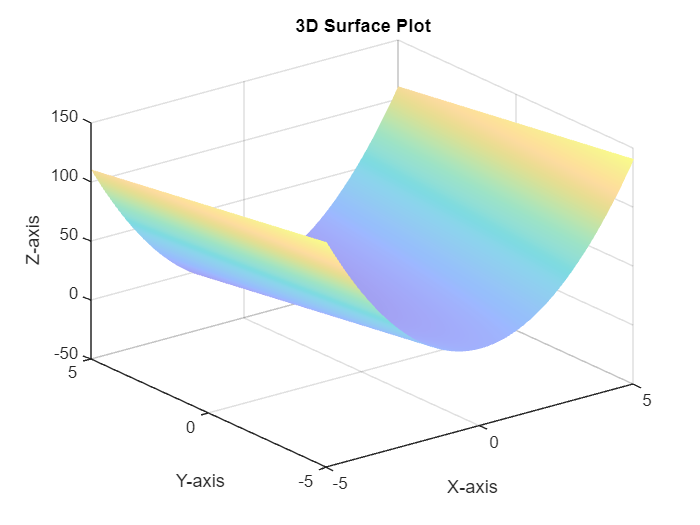

figure;
grid on;
xlim manual;
ylim manual;
surf(X, Y, Z);
shading interp;
alpha(0.5);
xlabel('X-axis');
ylabel('Y-axis');
zlabel('Z-axis');
title('3D Surface Plot');
hold on;

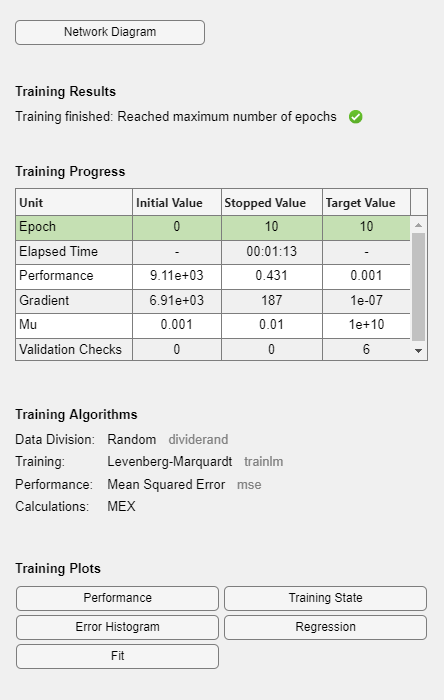

S2 = 10;
net = fitnet(S2);
net.trainParam.goal = 0.001;
net.trainParam.show = NaN;
net.trainParam.epochs = 10;
[net, tr] = train(net, P, T);

Z1 = net(P_test);

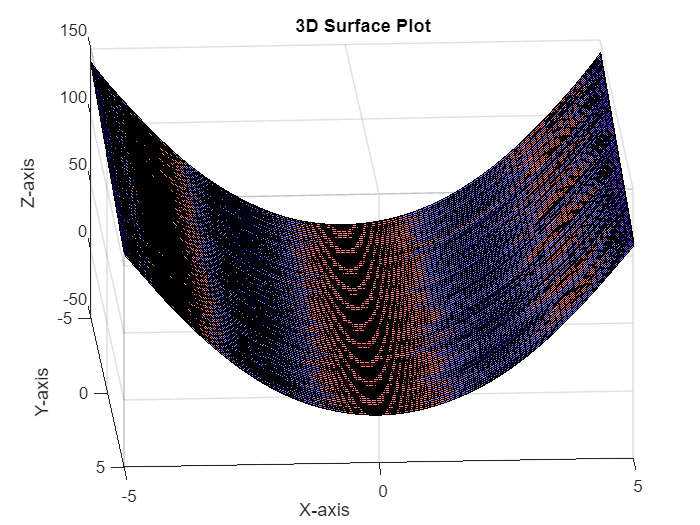

figure;
surf(X, Y, Z, 'FaceColor', 'r');
alpha(0.5);
hold on;
surf(X, Y, Z1, 'FaceColor', 'b');
alpha(0.5);
xlabel('X-axis');
ylabel('Y-axis');
zlabel('Z-axis');
title('3D Surface Plot');